# Data Driven Simulation Nuclear Norm

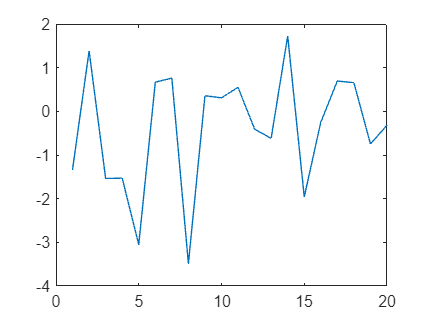

% Define system dimensions
statenum = 3;
outputnum = 1;
inputnum = 1;
maxTime = 20; % Total time for simulation of historical data
predTime = 1; % Part of the time that is the future

% Parameters for the algorithm
n_max = statenum; % Upper bound on the order (known from drss)
l_max = ceil(statenum / outputnum); % A simple guess for lag
delta = predTime; % Length of blocks processed in each iteration

% Create a discrete-time random state space model
sys = drss(statenum, outputnum, inputnum);

% Generate a persistently exciting input for historical data
% For example, a random signal
u_trajectory = randn(inputnum, maxTime);

% New input for prediction
newInputTime = predTime; % Length of new input
uf = randn(inputnum, newInputTime); % New input sequence
%uf = zeros(inputnum,1); %zero input

% Simulate the system to generate historical outputs
% Assuming zero initial state for simplicity
x0 = zeros(statenum, 1); % Initial state
[data, t, x] = lsim(sys, u_trajectory', linspace(0, maxTime-1, maxTime), x0);

plot(data)

data = data/10

data =    -0.1329
    0.1385
   -0.1539
   -0.1530
   -0.3051
    0.0668
    0.0761
   -0.3489
    0.0357
    0.0309


dataLength = length(data);

lag = 10;

% Create the full Hankel matrix without missing values initially
HankelMatrix = mosaicHankel(u_trajectory, data, lag) 

HankelMatrix =    -1.8759   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905
   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104
    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680
    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917
   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864
   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670
    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727
   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1577
   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1


% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0



disp(HankelMatrix);

   -1.8759   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905
   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104
    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680
    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917
   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864
   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670
    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727
   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1577
   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1577   -0.8157
 

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin quiet %sdp for logs
    variable CompleteHankel(size(HankelMatrix))
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end
% Check the completion status
disp(cvx_status);

Solved


% Extract the predicted values from the completed Hankel matrix
CompleteHankel

CompleteHankel =    -1.8759   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905
   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104
    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680
    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917
   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864
   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670
    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727
   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1577
   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0

HankelMatrix

HankelMatrix =    -1.8759   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905
   -0.3983    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104
    0.0980    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680
    0.8369   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917
   -1.3884   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864
   -0.8876    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670
    1.6685   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727
   -0.1247   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1577
   -0.1082   -0.2554    0.1905   -0.1104   -1.0680    1.1917    0.3864   -0.2670   -0.4727   -0.1


predictedValues = CompleteHankel(end, end-numPredict+1:end);
disp('Predicted value:');

Predicted value:


disp(predictedValues);

   -0.0395



disp('Actual value:');

Actual value:


disp(transpose(data(end-numPredict+1:end)))

   -0.0316



%rmse(predictedValues,transpose(data(end-numPredict+1:end)))
currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)

currentError = 0.1984

bestLag = 2;
lowestError = inf;

cvx_begin quiet

%checking the lag performance
for lag=1:maxTime-1
    dataLength = length(data);
    L = lag;  % Number of lags (rows in the Hankel matrix)
    N = dataLength - L + 1;  % Total columns in the Hankel matrix
    
    % Create the full Hankel matrix without missing values initially
    HankelMatrix = mosaicHankel(u_trajectory, data, L) 

    % Define the number of points we want to predict (missing at the end)
    numPredict = 1;
    
    % Create a logical mask for the Hankel matrix with all ones (no missing data)
    mask = true(size(HankelMatrix));
    
    % Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
    % These points appea5r in the last 'numPredict' rows of the last columns
    for i = 1:numPredict
        mask(end-i+1, end-numPredict+i:end) = false;
    end
    
    % Now, apply the mask to set the last 'numPredict' points as NaN (missing)
    HankelMatrix(~mask) = NaN;
    
    % Display the mask and modified Hankel matrix to check
    disp(mask);
    disp(HankelMatrix);
    % Proceed with matrix completion using the nuclear norm minimization (using CVX)
    cvx_begin sdp
        variable CompleteHankel(L, N)
        minimize(norm_nuc(CompleteHankel))
        subject to
            % Ensure the known entries remain the same
            CompleteHankel(mask) == HankelMatrix(mask);
    cvx_end
    % Check the completion status
    disp(cvx_status);
    % Extract the predicted values from the completed Hankel matrix
    predictedValues = CompleteHankel(end, end-numPredict+1:end);
    disp('Predicted values:');
    disp(predictedValues);
    disp(transpose(data(end-numPredict+1:end)))
    %rmse(predictedValues,transpose(data(end-numPredict+1:end)))
    currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)
    if lowestError > currentError
        lowestError = currentError;
        bestLag = lag;
    end
end

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 19 equality constraints
------------------------------------------------------------

 num. of constraints = 19
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.3e-08|1.0e-01|1.7e+02| 1.460753e+02  2.907841e-02| 0:0:00| chol  1  1 
 2|0.975|1.000|5.2e-08|1.0e-02|5.7e+00| 5.646639e+00  5.262869e-02| 0:0:00| chol  1  1 
 3|1.000|0.938|1.4e-08|1.6e-03|1.8e+00| 2.210289e+00  4.165486e-01| 0:0:00| chol  1  1 
 4|0.985|1.

Solved


Predicted values:


     0



   -0.1095



currentError = Inf

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 37 equality constraints
------------------------------------------------------------

 num. of constraints = 37
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.8e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.6e-08|1.0e-01|1.7e+02| 1.460878e+02  5.813426e-02| 0:0:00| chol  1  1 
 2|0.970|1.000|6.5e-08|1.0e-02|6.4e+00| 6.450928e+00  1.051161e-01| 0:0:00| chol  1  1 
 3|1.000|0.937|1.8e-08|1.6e-03|2.0e+00| 2.728241e+00  7.654676e-01| 0:0:00| chol  1  1 
 4|0.973|1.

Solved


Predicted values:


   -0.0338



   -0.1095



currentError = 2.2365

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 53 equality constraints
------------------------------------------------------------

 num. of constraints = 53
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.8e-08|1.0e-01|1.7e+02| 1.460991e+02  8.448046e-02| 0:0:00| chol  1  1 
 2|0.966|1.000|7.3e-08|1.0e-02|7.0e+00| 7.090853e+00  1.526052e-01| 0:0:00| chol  1  1 
 3|1.000|0.942|2.1e-08|1.5e-03|2.1e+00| 3.104454e+00  1.045431e+00| 0:0:00| chol  1  1 
 4|0.973|1.

Solved


Predicted values:


   -0.0464



   -0.1095



currentError = 1.3579

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 67 equality constraints
------------------------------------------------------------

 num. of constraints = 67
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.6e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.9e-08|1.0e-01|1.7e+02| 1.461096e+02  1.086656e-01| 0:0:00| chol  1  1 
 2|0.964|1.000|7.8e-08|1.0e-02|7.3e+00| 7.409667e+00  1.962218e-01| 0:0:00| chol  1  1 
 3|1.000|0.946|2.2e-08|1.5e-03|2.1e+00| 3.379933e+00  1.316392e+00| 0:0:00| chol  1  1 
 4|0.985|1.

Solved


Predicted values:


   -0.0416



   -0.1095



currentError = 1.6298

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 79 equality constraints
------------------------------------------------------------

 num. of constraints = 79
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.8e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.0e-08|1.0e-01|1.7e+02| 1.461192e+02  1.309602e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.2e-08|1.0e-02|7.4e+00| 7.572556e+00  2.364678e-01| 0:0:00| chol  1  1 
 3|1.000|0.947|2.4e-08|1.5e-03|2.0e+00| 3.615409e+00  1.577993e+00| 0:0:00| chol  1  1 
 4|0.988|1.

Solved


Predicted values:


   -0.0403



   -0.1095



currentError = 1.7177

   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 89 equality constraints
------------------------------------------------------------

 num. of constraints = 89
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.0e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.1e-08|1.0e-01|1.7e+02| 1.461277e+02  1.508689e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.5e-08|1.0e-02|7.5e+00| 7.639840e+00  2.724135e-01| 0:0:00| chol  1  1 
 3|1.000|0.945|2.5e-08|1.5e-03|2.0e+00| 3.811863e+00  1.811336e+00| 0:0:00| chol  1  1 
 4|0.997|1.

Solved


Predicted values:


   -0.0433



   -0.1095



currentError = 1.5300

   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 97 equality constraints
------------------------------------------------------------

 num. of constraints = 97
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.1e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.1e-08|1.0e-01|1.7e+02| 1.461346e+02  1.668435e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.7e-08|1.0e-02|7.5e+00| 7.648194e+00  3.012789e-01| 0:0:00| chol  1  1 
 3|1.000|0.944|2.5e-08|1.5e-03|2.0e+00| 3.971023e+00  2.010440e+00| 0:0:00| chol  1  1 
 4|1.000|1.

Solved


Predicted values:


   -0.0412



   -0.1095



currentError = 1.6596

   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   

 
Calling SDPT3 4.0: 232 variables, 103 equality constraints
------------------------------------------------------------

 num. of constraints = 103
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461384e+02  1.757041e-01| 0:0:00| chol  1  1 
 2|0.964|1.000|8.8e-08|1.0e-02|7.4e+00| 7.562549e+00  3.173749e-01| 0:0:00| chol  1  1 
 3|1.000|0.943|2.6e-08|1.5e-03|1.9e+00| 4.077397e+00  2.166597e+00| 0:0:00| chol  1  1 
 4|0.999|

Solved


Predicted values:


   -0.0450



   -0.1095



currentError = 1.4349

   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.1404   -0.0263   -0.1213  

 
Calling SDPT3 4.0: 232 variables, 107 equality constraints
------------------------------------------------------------

 num. of constraints = 107
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461419e+02  1.836385e-01| 0:0:00| chol  1  1 
 2|0.965|1.000|8.9e-08|1.0e-02|7.3e+00| 7.473090e+00  3.318169e-01| 0:0:00| chol  1  1 
 3|1.000|0.942|2.7e-08|1.5e-03|1.9e+00| 4.178528e+00  2.315452e+00| 0:0:00| chol  1  1 
 4|0.999|

Solved


Predicted values:


   -0.0452



   -0.1095



currentError = 1.4209

   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
 

 
Calling SDPT3 4.0: 232 variables, 109 equality constraints
------------------------------------------------------------

 num. of constraints = 109
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461429e+02  1.860304e-01| 0:0:00| chol  1  1 
 2|0.965|1.000|8.9e-08|1.0e-02|7.2e+00| 7.461343e+00  3.362501e-01| 0:0:00| chol  1  1 
 3|1.000|0.945|2.7e-08|1.5e-03|1.9e+00| 4.243928e+00  2.399407e+00| 0:0:00| chol  1  1 
 4|0.966|

Solved


Predicted values:


   -0.0935



   -0.1095



currentError = 0.1713

   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903 

 
Calling SDPT3 4.0: 232 variables, 109 equality constraints
------------------------------------------------------------

 num. of constraints = 109
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461429e+02  1.860304e-01| 0:0:00| chol  1  1 
 2|0.965|1.000|8.9e-08|1.0e-02|7.2e+00| 7.461343e+00  3.362501e-01| 0:0:00| chol  1  1 
 3|1.000|0.945|2.7e-08|1.5e-03|1.9e+00| 4.243928e+00  2.399407e+00| 0:0:00| chol  1  1 
 4|0.966|

Solved


Predicted values:


   -0.0935



   -0.1095



currentError = 0.1713

   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294

 
Calling SDPT3 4.0: 232 variables, 107 equality constraints
------------------------------------------------------------

 num. of constraints = 107
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461419e+02  1.836385e-01| 0:0:00| chol  1  1 
 2|0.965|1.000|8.9e-08|1.0e-02|7.3e+00| 7.473090e+00  3.318169e-01| 0:0:00| chol  1  1 
 3|1.000|0.942|2.7e-08|1.5e-03|1.9e+00| 4.178528e+00  2.315452e+00| 0:0:00| chol  1  1 
 4|0.999|

Solved


Predicted values:


   -0.0452



   -0.1095



currentError = 1.4209

   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.0317    0.0672    0.04

 
Calling SDPT3 4.0: 232 variables, 103 equality constraints
------------------------------------------------------------

 num. of constraints = 103
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.2e-08|1.0e-01|1.7e+02| 1.461384e+02  1.757041e-01| 0:0:00| chol  1  1 
 2|0.964|1.000|8.8e-08|1.0e-02|7.4e+00| 7.562549e+00  3.173749e-01| 0:0:00| chol  1  1 
 3|1.000|0.943|2.6e-08|1.5e-03|1.9e+00| 4.077397e+00  2.166597e+00| 0:0:00| chol  1  1 
 4|0.999|

Solved


Predicted values:


   -0.0450



   -0.1095



currentError = 1.4349

   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   1
   1   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 97 equality constraints
------------------------------------------------------------

 num. of constraints = 97
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.1e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.1e-08|1.0e-01|1.7e+02| 1.461346e+02  1.668435e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.7e-08|1.0e-02|7.5e+00| 7.648194e+00  3.012789e-01| 0:0:00| chol  1  1 
 3|1.000|0.944|2.5e-08|1.5e-03|2.0e+00| 3.971023e+00  2.010440e+00| 0:0:00| chol  1  1 
 4|1.000|1.

Solved


Predicted values:


   -0.0412



   -0.1095



currentError = 1.6596

   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   1
   1   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003   -0.1537
    0.0268    0.0759   -0.0330   -0.1003   -0.1537   -0.2032
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.0263   -0.1213    0.1265   -0.0317    0.0672    0.0414
   -0.1213    0.1265   -0.0317    0.0672    0.0414   -0.0728
    0.1265   -0.0317    0.0672    0.0414   -0.0728   -0.1053
   -0.0317    0.0672    0.0414   -0.0728   -0.1053   -0.0903
    0.0672    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
    0.0414   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 89 equality constraints
------------------------------------------------------------

 num. of constraints = 89
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.0e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.1e-08|1.0e-01|1.7e+02| 1.461277e+02  1.508689e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.5e-08|1.0e-02|7.5e+00| 7.639840e+00  2.724135e-01| 0:0:00| chol  1  1 
 3|1.000|0.945|2.5e-08|1.5e-03|2.0e+00| 3.811863e+00  1.811336e+00| 0:0:00| chol  1  1 
 4|0.997|1.

Solved


Predicted values:


   -0.0433



   -0.1095



currentError = 1.5300

   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330   -0.1003
    0.0268    0.0759   -0.0330   -0.1003   -0.1537
    0.0759   -0.0330   -0.1003   -0.1537   -0.2032
   -0.0330   -0.1003   -0.1537   -0.2032   -0.0704
   -0.1003   -0.1537   -0.2032   -0.0704   -0.1404
   -0.1537   -0.2032   -0.0704   -0.1404   -0.0263
   -0.2032   -0.0704   -0.1404   -0.0263   -0.1213
   -0.0704   -0.1404   -0.0263   -0.1213    0.1265
   -0.1404   -0.0263   -0.1213    0.1265   -0.0317
   -0.0263   -0.1213    0.1265   -0.0317    0.0672
   -0.1213    0.1265   -0.0317    0.0672    0.0414
    0.1265   -0.0317    0.0672    0.0414   -0.0728
   -0.0317    0.0672    0.0414   -0.0728   -0.1053
    0.0672    0.0414   -0.0728   -0.1053   -0.0903
    0.0414   -0.0728   -0.1053   -0.0903   -0.1294
   -0.0728   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 79 equality constraints
------------------------------------------------------------

 num. of constraints = 79
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.8e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|2.0e-08|1.0e-01|1.7e+02| 1.461192e+02  1.309602e-01| 0:0:00| chol  1  1 
 2|0.963|1.000|8.2e-08|1.0e-02|7.4e+00| 7.572556e+00  2.364678e-01| 0:0:00| chol  1  1 
 3|1.000|0.947|2.4e-08|1.5e-03|2.0e+00| 3.615409e+00  1.577993e+00| 0:0:00| chol  1  1 
 4|0.988|1.

Solved


Predicted values:


   -0.0403



   -0.1095



currentError = 1.7177

   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   0



   -0.0121    0.0268    0.0759   -0.0330
    0.0268    0.0759   -0.0330   -0.1003
    0.0759   -0.0330   -0.1003   -0.1537
   -0.0330   -0.1003   -0.1537   -0.2032
   -0.1003   -0.1537   -0.2032   -0.0704
   -0.1537   -0.2032   -0.0704   -0.1404
   -0.2032   -0.0704   -0.1404   -0.0263
   -0.0704   -0.1404   -0.0263   -0.1213
   -0.1404   -0.0263   -0.1213    0.1265
   -0.0263   -0.1213    0.1265   -0.0317
   -0.1213    0.1265   -0.0317    0.0672
    0.1265   -0.0317    0.0672    0.0414
   -0.0317    0.0672    0.0414   -0.0728
    0.0672    0.0414   -0.0728   -0.1053
    0.0414   -0.0728   -0.1053   -0.0903
   -0.0728   -0.1053   -0.0903   -0.1294
   -0.1053   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 67 equality constraints
------------------------------------------------------------

 num. of constraints = 67
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.6e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.9e-08|1.0e-01|1.7e+02| 1.461096e+02  1.086656e-01| 0:0:00| chol  1  1 
 2|0.964|1.000|7.8e-08|1.0e-02|7.3e+00| 7.409667e+00  1.962218e-01| 0:0:00| chol  1  1 
 3|1.000|0.946|2.2e-08|1.5e-03|2.1e+00| 3.379933e+00  1.316392e+00| 0:0:00| chol  1  1 
 4|0.985|1.

Solved


Predicted values:


   -0.0416



   -0.1095



currentError = 1.6298

   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   1
   1   1   0



   -0.0121    0.0268    0.0759
    0.0268    0.0759   -0.0330
    0.0759   -0.0330   -0.1003
   -0.0330   -0.1003   -0.1537
   -0.1003   -0.1537   -0.2032
   -0.1537   -0.2032   -0.0704
   -0.2032   -0.0704   -0.1404
   -0.0704   -0.1404   -0.0263
   -0.1404   -0.0263   -0.1213
   -0.0263   -0.1213    0.1265
   -0.1213    0.1265   -0.0317
    0.1265   -0.0317    0.0672
   -0.0317    0.0672    0.0414
    0.0672    0.0414   -0.0728
    0.0414   -0.0728   -0.1053
   -0.0728   -0.1053   -0.0903
   -0.1053   -0.0903   -0.1294
   -0.0903   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 53 equality constraints
------------------------------------------------------------

 num. of constraints = 53
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.2e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.8e-08|1.0e-01|1.7e+02| 1.460991e+02  8.448046e-02| 0:0:00| chol  1  1 
 2|0.966|1.000|7.3e-08|1.0e-02|7.0e+00| 7.090853e+00  1.526052e-01| 0:0:00| chol  1  1 
 3|1.000|0.942|2.1e-08|1.5e-03|2.1e+00| 3.104454e+00  1.045431e+00| 0:0:00| chol  1  1 
 4|0.973|1.

Solved


Predicted values:


   -0.0464



   -0.1095



currentError = 1.3579

   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   0



   -0.0121    0.0268
    0.0268    0.0759
    0.0759   -0.0330
   -0.0330   -0.1003
   -0.1003   -0.1537
   -0.1537   -0.2032
   -0.2032   -0.0704
   -0.0704   -0.1404
   -0.1404   -0.0263
   -0.0263   -0.1213
   -0.1213    0.1265
    0.1265   -0.0317
   -0.0317    0.0672
    0.0672    0.0414
    0.0414   -0.0728
   -0.0728   -0.1053
   -0.1053   -0.0903
   -0.0903   -0.1294
   -0.1294       NaN



 
Calling SDPT3 4.0: 232 variables, 37 equality constraints
------------------------------------------------------------

 num. of constraints = 37
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.8e-01|1.3e+01|3.2e+03| 1.654157e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|1.6e-08|1.0e-01|1.7e+02| 1.460878e+02  5.813426e-02| 0:0:00| chol  1  1 
 2|0.970|1.000|6.5e-08|1.0e-02|6.4e+00| 6.450928e+00  1.051161e-01| 0:0:00| chol  1  1 
 3|1.000|0.937|1.8e-08|1.6e-03|2.0e+00| 2.728241e+00  7.654676e-01| 0:0:00| chol  1  1 
 4|0.973|1.

Solved


Predicted values:


   -0.0338



   -0.1095



currentError = 2.2365

Results:

%rmse(predictedValues,transpose(data(end-numPredict+1:end)))

disp("best lag: "+bestLag)

best lag: 11


disp("lowest relative error: "+lowestError)

lowest relative error: 0.17127
